This lesson is for resume  and reduce de code explained in previous lessons.

initPose = [ 0.5; 0.5; 1.5707]; % [x ; y ; theta]   
goalPose = [2; 2.5;0];

R = 0.1; 
L = 0.12; 

viz = Visualizer2D;
viz.mapName = 'map';
viz.robotRadius = L; 
mobileRobot = DifferentialDrive(R,L);


Prepare map  to calculate path

                       %generateAugmentedMap(path, treshold, scale,robotRadio)
[map, mapDilatation]  = generateAugmentedMap(which('world1.png'), 0.1, 10, L);

                    %getPathRRT(map,initPose,goalPose,MinTurningRadius,ValidationDistance,MaxConnectionDistance,MaxIterations)
[pthObj, solnInfo] = getPathRRT(mapDilatation,initPose,goalPose,0.2,.1,0.2,30000);

              %controllerPP(pthObj,LookaheadDistance,DesiredLinearVelocity,MaxAngularVelocity)
[controller] = controllerPP(pthObj,0.05,0.1,pi/6);

Execute simulation.

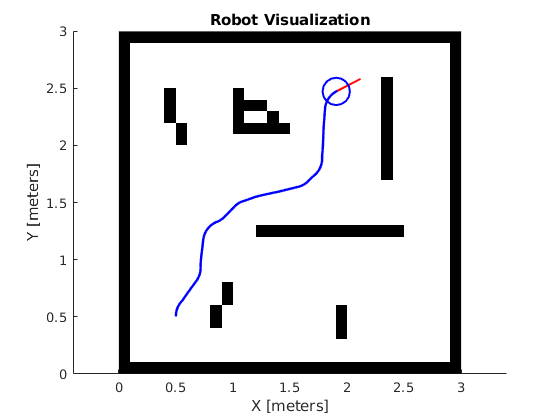

currentPose = initPose;
[sampleTime,tVec,r] = simulTime(0.1,38);
for idx = 2:numel(tVec) 
    
    if( sqrt( (currentPose(1)-pthObj.States(end,1))^2 + (currentPose(2)-pthObj.States(end,2))^2 )  < L/2  )
       break
    end
    
    [vRef,wRef,lookAheadPt] = controller(currentPose);
    bodyV = [vRef;0;wRef];
    
    % Convert from robot body to world
    vel =  bodyToWorld(bodyV,currentPose);  
   
    % Perform forward discrete integration step
    currentPose = currentPose + vel * sampleTime; 
    
    % Update visualization
    viz(currentPose);

    %Wait for visualization rate
    waitfor(r);
    
end